## mu 综合

### 电机建模

clear
clc
close

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% 电机参数（FMC05707）腕关节 %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
s = tf('s');

% I = 80; % 减速比
I = 1;  % 控制电机位置，而非关节输出端位置时，将减速比调整为1

R = 1.93; % 线电阻 (Ω)
Ls = 1.79e-3; % 线电感 (H)
k_e = 8; % 反电动势常数 (V/krpm)

k_b = 2e-5; % 黏性摩擦系数 % 待定
k_t = 0.132; % 转矩常数 (Nm/A)
Jm = 9.6e-6; % 转动惯量 (kg*m^2)

pp = 16/2; % 极对数
omega_e = 3000*2*pi/60*pp; % 电角速度，在电流环中预先选定
lamda = sqrt(2)*k_e*9.55/sqrt(3)/pp/1e3; % 永磁体磁链常数 (Wb)

p_oil = 10e6; % 油液压力 (Pa)
mu0 = 71.3e-3; % 液压油的额定动力黏度 (Pa·s)
alpha_mu = 1/(9.43e7+2.8e-1*p_oil); % 黏性压力系数 (1/Pa)
mu = mu0*exp(alpha_mu*p_oil); % 实际动力黏度 (Pa·s) 

d_r1 = 3.94e-2; % 无框力矩电机转子外径 (m)
d_r2 = 3.19e-2; % 旋转变压器转子外径 (m)

l_rs1 = 1e-3; % 无框力矩电机转子与定子之间的径向缝隙长度 (m) %待更正%
l_rs2 = 9e-5; % 旋转变压器转子与定子之间的径向缝隙长度 (m)

l_r1 = 9e-3; % 无框力矩电机转子长度 (m)
l_r2 = 2.71e-2; % 旋转变压器转子长度 (m)

l_rh1 = 1.69e-3; % 无框力矩电机转子端部与左端轴承的之间的距离(m)
l_rh11 = 1.01e-3; % 无框力矩电机转子端部与右端轴承的之间的距离(m)
l_rh2 = 1.23e-3; % 旋转变压器端部与左端轴承的之间的距离(m)

d_b1 = 2.16e-2; % 无框力矩电机转子端部与左端轴承的之间的轴径(m)
d_b11 = 1.93e-2; % 无框力矩电机转子端部与右端轴承的之间的轴径(m)
d_b2 = 1.54e-2; % 旋转变压器转子端部与左端轴承的之间的轴径(m)

% Kd = (pi*l_r1*d_r1^3/(4*l_rs1)+pi*l_r2*d_r2^3/(4*l_rs2)+pi*(d_r1^4-d_b1^4)/(32*l_rh1)+pi*(d_r1^4-d_b11^4)/(32*l_rh11)+pi*(d_r2^4-d_b2^4)/(32*l_rh2))*I*mu;
Kd = 0; % 当关节未充入油液时，将Kd设为0

状态变量：$x={\left\lbrack \theta_m \;\;{\dot{\theta} }_m \right\rbrack }^T$

输入：$u=i_q$

输出：$y=\theta_m$

%%%%%%%%%%%%%%%%%
%%% 确定性模型 %%%
%%%%%%%%%%%%%%%%%
A = [0 1; 0 (-k_b*I-Kd)/(Jm*I)];
B = [0; k_t/(Jm*I)];
C = [1 0];
D = 0;
G = ss(A,B,C,D);
getGainCrossover(G,1)

ans =      1.172511408574167e+02



%%%%%%%%%%%%%%%%%%%
%%% 不确定性参数 %%%
%%%%%%%%%%%%%%%%%%%
% k_b = ureal('k_b',k_b,'Percentage',25);
k_t = ureal('k_t',k_t,'Percentage',10);
Jm = ureal('J',Jm,'Percentage',10);% 'AutoSimplify','full'

%%%%%%%%%%%%%%%%%%%
%%% 不确定性模型 %%%
%%%%%%%%%%%%%%%%%%%
A = [0 1; 0 (-k_b*I-Kd)/(Jm*I)];
B = [0; k_t/(Jm*I)];
C = [1 0];
D = 0;
uss = ss(A,B,C,D);

### 控制结构设计

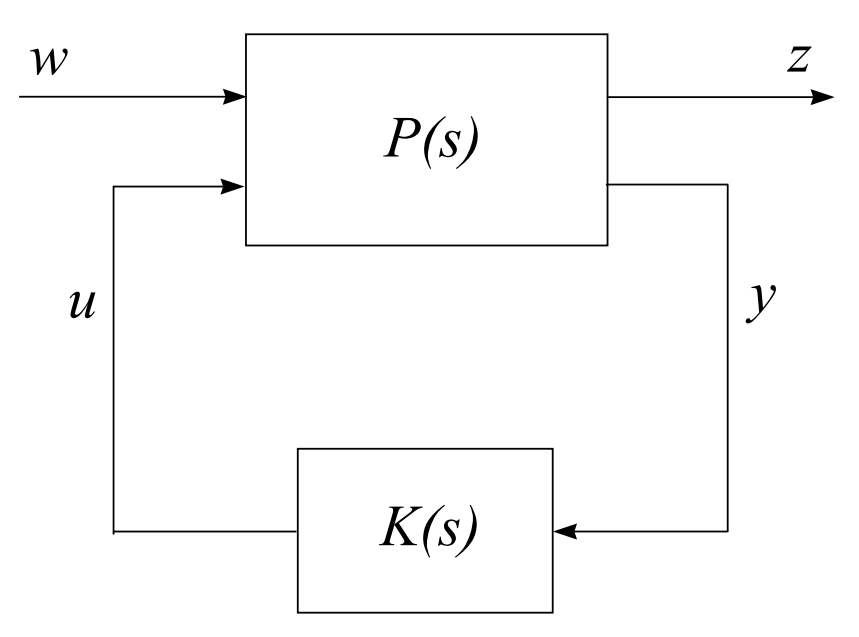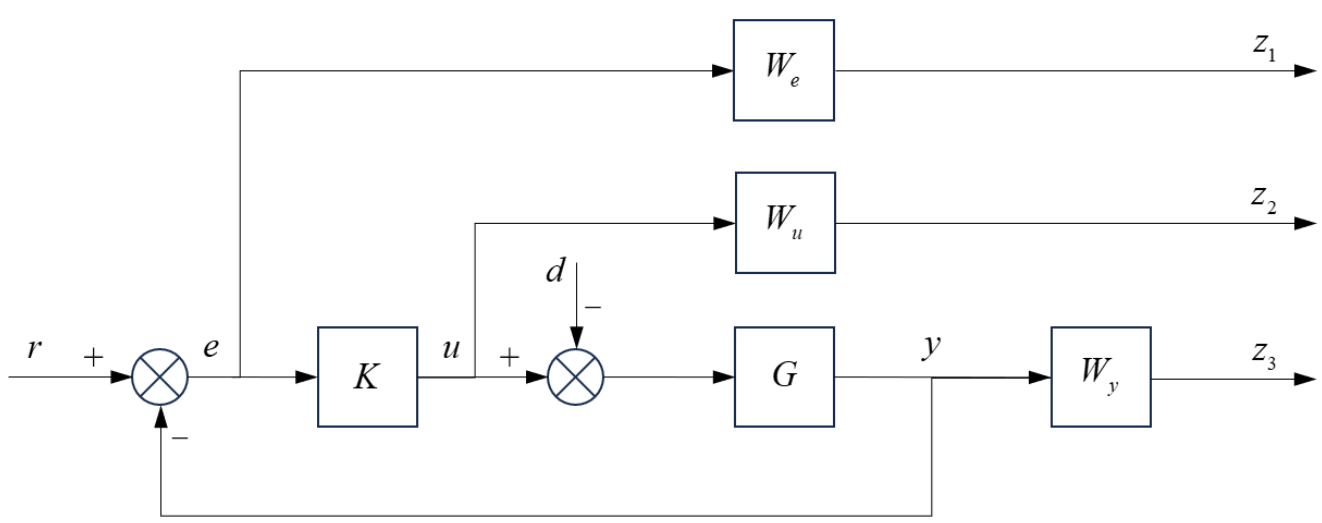

%%%%%%%%%%%%%%%%%%%
%%% 权函数的选择 %%%
%%%%%%%%%%%%%%%%%%%

%%% 误差权函数 %%%
We = 0.1*(s + 10)/(s+0.01);% 1114-2
% We = makeweight(100,0.5,0.1); % 1114-3

We.InputName = 'e';
We.OutputName = 'z1';

%%% 控制量权函数 %%%
% Wu = tf(2.5);% 1114-2
Wu = tf(10);

Wu.InputName = 'u';
Wu.OutputName = 'z2';

%%% 输出量权函数 %%%
Wy = tf(1); % 1114-2 1114-2-3
% Wy = tf(10); % 1114-3
% Wy = makeweight(0.1,20,10); % method 1

Wy.InputName = 'y';
Wy.OutputName = 'z3';

%%% 扰动权函数 %%%
Wd = tf(1);

Wd.InputName = 'd';
Wd.OutputName = 'D';

%%% 噪声权函数 %%%
Wn = tf(0);

Wn.InputName = 'n';
Wn.OutputName = 'N';

%%% P %%%
S1 = sumblk('e = r - f');
% S2 = sumblk('i = u - D');
S2 = sumblk('i = u + D'); % 将扰动输入调整为正
uss.InputName = 'i';
uss.OutputName = 'y';
S3 = sumblk('f = y + N'); 
inputs = {'r','d','n','u'};
outputs = {'z1','z2','z3','e'}; % https://ww2.mathworks.cn/help/robust/gs/model-uncertainty-in-simulink-for-robust-tuning.html
P = connect(We,Wu,Wy,Wd,Wn,S1,S2,S3,uss,inputs,outputs);

%%% mu 综合 %%%
opts = musynOptions('MixedMU','on','MaxIter', 10, 'UseParallel', true, 'FullDG', true); % 注意修改
[K_mu,CLperf,info] = musyn(P,1,1,opts); 

%%% 控制器降阶 %%%
N = order(K_mu);
Kred = reduce(K_mu,1:N);

for k=1:N
   Klow = Kred(:,:,k);
   CL = lft(P,Klow);
   [gamma,~] = musynperf(CL);
   if gamma.UpperBound < 1.05*CLperf % 注意修改此处
      break
   end
end 
order(Klow) % 阶数越高，超调越小？

% 参考输入到输出的传递函数
loops = loopsens(uss,Klow);
step(loops.To); % 参考信号跟踪的传递函数
norm(loops.To,'inf')

% 参考输入到控制量的传递函数
step(Klow*loops.So) % 限制控制量幅值的传递函数
norm(Klow*loops.So,'inf')

% 干扰到误差的传递函数
Klow.InputName = 'e';
Klow.OutputName = 'u';
inputs = {'d'};
outputs = {'e'}; % https://ww2.mathworks.cn/help/robust/gs/model-uncertainty-in-simulink-for-robust-tuning.html
P1 = connect(We,Wu,Wy,Wd,Wn,Klow,S1,S2,S3,uss,inputs,outputs);
step(P1)
title('');
xlabel('');
ylabel('');